clc
clear all
k=101;      % number of grid 
m=100;      % given in question m=(2*h*l^2/(k*t))
Z(1)=0;     %intial value of z 
f(1)=-1;    %intial value of f f=(1/(z-1))
dz=0.01;    % Grid size in space
dt=10^-5;   % Grid size in time 
n=1/dt;     % number of grid for time
theta_old=zeros(k); % initially asigning zero value to all theta
error=1;
error_required= 10^(-8); %estimation of error to reach steady state
l=0;  % l is  no of interation 
%Boundary condition
while error > error_required
     b(1)=1; b(k)=1; 
     a(1)=0; a(k)=-1;      
     c(1)=0; c(k)=0;      
     d=zeros(k);d(1)=1;
for i=2:k-1
      Z(i)=Z(i-1)+dz;
      f(i)=1/(Z(i)-1);
end
 % Interior Points 
  for i=2:k-1
       a(i)=-(dt/dz^2)+(dt/(2*dz))*f(i);
       b(i)=1+2*(dt/dz^2);
       c(i)=-(dt/dz^2)-(dt/(2*dz))*f(i)-m*dt*f(i);
       d(i)= theta_old(i);
  end
% Forward Elimination
for i=2:k
    r=a(i)/b(i-1);
    b(i)=b(i)-r*c(i-1);
    d(i)=d(i)-r*d(i-1);
    a(i)=0;
end
% Back Substitution
theta(k)=d(k)/b(k);
for i=k-1:-1:1
    theta(i)=(d(i)-c(i)*theta(i+1))/b(i);
end
% definition of error
   e=0;
for j=1:k
       e= e + ( theta(j)-theta_old(j))^2;
end
      error=sqrt(e); 
      l = l +1 ; %iteration value
      theta_old=theta;
   
    if l==100
         theta_save(1,:)=theta;
    end
    if l==500
         theta_save(2,:)=theta;
    end
    
end
      theta_save(3,:)=theta;
      

        


% solution of steady state problem of excercise 1
 B(1)=1;B(k)=1;
A(1)=0;A(k)=-1;
C(1)=0;C(k)=0;
D(1)=1;
dZ=0.01;
for i=2:k
    Z(i)=Z(i-1)+dZ;
    F(i)= Z(i)-1;
end    

for i=2:k
    A(i)=2*F(i)-dZ;
    B(i)=-4*F(i)+ (2*m*dZ*dZ);
    C(i)=2*F(i)+dZ;
    D(i)=0;
end

for i=2:k
    R=A(i)/B(i-1);
    B(i)=B(i)-R*C(i-1);
    D(i)=D(i)-R*D(i-1);
    A(i)=0;
end
theta_steady(k)=D(k)/B(k);
for i=k-1:-1:1
    theta_steady(i)=(D(i)-C(i)*theta_steady(i+1))/B(i);
end

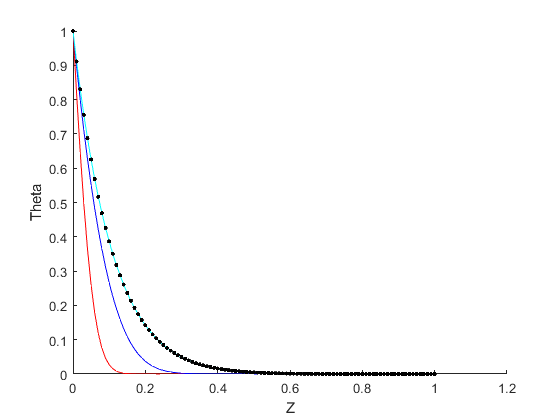

%plotting
hold on
plot(Z,theta_save(1,:),'color','r')
plot(Z,theta_save(2,:),'color','b')
plot(Z,theta_save(3,:),'color','c')
steady=plot(Z,theta,'color','k');
set(steady,'LineStyle','none','marker','.')
set(steady,'MarkerSize',7)
hold off
xlabel 'Z'
ylabel 'Theta'